Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Vacuum calculations (Section 13.5.3)

Volker Ziemann, 211112, CC-BY-SA-4.0

Here we describe a minimal version of the vacuum calculation code `vaktrak`, discussed in

- Volker Ziemann, *Vacuum tracking,* SLAC-PUB-5962, 1992.

It determines the longitudinal profile of the pressure and gasflow along a linear vacuum system in the regime of conduction limited flow. Such a vacuum system of $n$ elements is defined by a $n\times 6$ array, where the first column contains a code, describing the type of element, the second element contains a repeat-code for that element, and the next four entries are related to the length, conductance $c$ or $C$ , pump speed $s$ or $S$, and outgassing rate $q$ of the respective element. Here is a short summary, but check out the details in Section 13.5.3.

              supported codes with ordering: CODE,repeat,L,c,s,q

              Conductance only:    1, rep,  L,  c, 0,  0 

              Short pump:               2,   1,  0,  0, S,  0

              Short gas source:      3,   1,  0,  0, 0, dQ

              Generic element:       4, rep,  L,  c, s,  q  

Larger systems can be assembled from short sections with repmat() and flip().

We start the simulation by defining functions that return the $3\times 3$ matrices for the conductance, a short pump, and a short gas source.

clear all; close all
conduc=@(C)[1,-1/C,0; 0,1,0; 0,0,1];  % matrix for conductance
pump=@(S)[1,0,0;-S,1,0;0,0,1];        % matrix for short pump
outgas=@(dQ)[1,0,0;0,1,dQ;0,0,1];     % matrix for gas source, leak

Now we define a section `vacsys` of our vacuum system, defined by a localized outgassing source (code=3), a pipe, made of 100 segments, 10 cm long each, and a short pump with a pump pseed of 100 l/s.

vaksys=[ 3,     1,     0,    0,    0,    1e-6;   % outgas, dQ
         1,   100,   0.1,   10,    0,    0;      % conductance, c
         2,     1,     0,    0,  100,    0]     % pump, S

vaksys =     3.0000    1.0000         0         0         0    0.0000
    1.0000  100.0000    0.1000   10.0000         0         0
    2.0000    1.0000         0         0  100.0000         0


The vacuum system v consists of two sections vaksys of which the second one is traversed in the reverse order. Finally we repeat this system 2 times and call the entire system `beamline`, just as we did for the beam optical systems in Chapter 3.

v=[vaksys; flip(vaksys,1)];
beamline=repmat(v,2,1)      % description of the complete system

beamline =     3.0000    1.0000         0         0         0    0.0000
    1.0000  100.0000    0.1000   10.0000         0         0
    2.0000    1.0000         0         0  100.0000         0
    2.0000    1.0000         0         0  100.0000         0
    1.0000  100.0000    0.1000   10.0000         0         0
    3.0000    1.0000         0         0         0    0.0000
    3.0000    1.0000         0         0         0    0.0000
    1.0000  100.0000    0.1000   10.0000         0         0
    2.0000    1.0000         0         0  100.0000         0
    2.0000    1.0000         0         0  100.0000         0


The following lines are needed for accounting purposes: `nlines` are the number of lines in the `beamline`, `nmat `is the number of matrices and `Racc` will be filled with all the transfer matrices from the start of the system to the end of each segment, while `spos` keeps track of the longitudinal position of segments.

nlines=size(beamline,1);      % number of elements in beamline
nmat=sum(beamline(:,2))+1;    % number of matrices, incl repeat count           
Racc=zeros(3,3,nmat);         % accumulated transfer matrices
Racc(:,:,1)=eye(3);           % initialize the first one
spos=zeros(nmat,1);           % array for element (end-)positions

In the next snippet we loop over all lines in the beamline and then over all segments and then assign `Rcurr` to the $3\times 3$ matrix for the appropriate element (as specified by the code in the first column of `beamline`). After these loops, we left-multiply `Rcurr` to the transfer matrix up to the previous element ` Racc(:,:,ic-1)` and update` spos`. Finally we give the transfer matrix that takes us to the end the name `R0`.

ic=1;
for line=1:nlines             % loop over elements
  for seg=1:beamline(line,2)  % and over the segements of each element
    ic=ic+1;                  % element counter
    Rcurr=eye(3);             % initialize to unit matrix
    switch beamline(line,1)   % brach accoding to element
      case 1       % pure conductance
        C=beamline(line,4)/beamline(line,3);   % C=c/L
        Rcurr=conduc(C);                       % large C 
      case 2       % short pump, zero length
        Rcurr=pump(beamline(line,5));          % large S
      case 3  % point-like gas source, zero length
        Rcurr=outgas(beamline(line,6));        % large dQ
      case 4  % generic element, c,s,q,L are all given
        Rcurr=csql(beamline(line,4),beamline(line,5),...
          beamline(line,6),beamline(line,3));
      otherwise
         disp('unsupported code')
    end
    Racc(:,:,ic)=Rcurr*Racc(:,:,ic-1);      % add new element  
    spos(ic)=spos(ic-1)+beamline(line,3);   % update the position
  end
end
R0=Racc(:,:,end);    % alias for the start-to-end matrix

If we assume that the entire system is flanged off at the ends (gasflow: `Ql=Qr=0`), we can find the equilibrium pressure on the left end `Pl` and at the right end `Pr` from `R0`. From this we construct the $3\times 1$ vector with the initial condition `P0r` and propagate it through the vacuum system in the loop over` k`.

Pr=-R0(2,3)/R0(2,1);
Pl=R0(1,3)-R0(1,1)*R0(2,3)/R0(2,1);
P0r=[Pr;0;1]; % vector at start
pressure=zeros(nmat,1); gasflow=pressure;   % allocate memory
for k=1:nmat            % loop over all elements
  PP=Racc(:,:,k)*P0r;   % and calculate [P;Q;1] at end of each element     
  pressure(k)=PP(1);    % stuff into arrays used for plotting
  gasflow(k)=PP(2);     
end

At this point we are ready to display the pressure profile along our vacuum system in the top plot and the corresponding gas flow in the bottom plot.

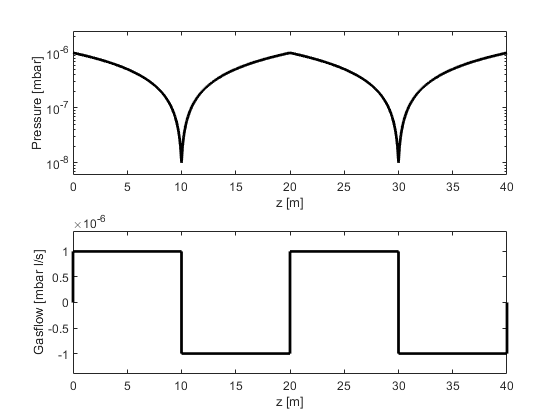

subplot(2,1,1); semilogy(spos,pressure,'k','LineWidth',2); 
xlim([0,spos(end)]); ylim([0.6*min(pressure),2.5*max(pressure)])
xlabel('z [m]'); ylabel('Pressure [mbar]');
subplot(2,1,2); plot(spos,gasflow,'k','LineWidth',2); 
xlim([0,spos(end)]); ylim([1.4*min(gasflow),1.4*max(gasflow)])
xlabel('z [m]'); ylabel('Gasflow [mbar l/s]')  

Now define your own vacuum system and simulate it.

## Appendix

here we define a function csql() that receives the per-meter conductance c, the per-meter pump speed s, the per-meter outgassing q, and the length L of an element and returns the transfer matrix from Equation 13.3.

function R=csql(c,s,q,L)
R=eye(3);
sq=sqrt(s/c); cc=cosh(sq*L); ss=sinh(sq*L); 
R(1,1)=cc;
R(1,2)=-ss/(c*sq);
R(1,3)=-q*(cc-1)/s;
R(2,1)=-c*sq*ss;
R(2,2)=cc;
R(2,3)=q*ss/sq;
end